inv = "55";
data_load = load("id_data\IBR="+inv+"_u=0.04.mat");
h = data_load.h

h = 0.0100


M = 1*ones(1,3);
D = 1*ones(1,3);
R_sg = 7; %Play with this one if ID not good enough (6,7 or 8)
T_sg = 6;
R_c = 4;
T_c = 0.1;
T_mpc = 1;
K_mpc = 40;
K_dis = 1*ones(1,3);

L = -7*ones(1,3);
beta = 1*ones(1,3);

params = {M; D; R_sg; T_sg; R_c; T_c; T_mpc; K_mpc; K_dis; L; beta};
init_sys = idgrey(@ssm,params,'c');

%Min
init_sys.Structure.Parameters(1).Minimum = 0;
init_sys.Structure.Parameters(2).Minimum = 0;
init_sys.Structure.Parameters(3).Minimum = 0;
init_sys.Structure.Parameters(4).Minimum = 0;
init_sys.Structure.Parameters(5).Minimum = 0;
init_sys.Structure.Parameters(6).Minimum = 0;
init_sys.Structure.Parameters(7).Minimum = 0;
init_sys.Structure.Parameters(8).Minimum = 0;
init_sys.Structure.Parameters(9).Minimum = 0;

%Max
init_sys.Structure.Parameters(10).Maximum = 0;

power_sys = init_sys;

%Sequential du Training
locs = [0,17,16];

for loc = locs
    data_train = get_data("id_data\IBR="+inv+"_loc="+loc+".mat", inv);
    opt = greyestOptions('SearchMethod','lsqnonlin', 'Display', 'on');
    opt.SearchOptions.MaxIterations = 50;
    power_sys = greyest(data_train, power_sys, opt);
    disp("Done with: "+loc)
end

Done with: 0


Done with: 17


Done with: 16



%Sequential u Training
sizes = [-0.04, -0.03, -0.02, 0.02, 0.03, 0.04];

%Free
power_sys.Structure.Parameters(5).Free = true;
power_sys.Structure.Parameters(6).Free = true;
power_sys.Structure.Parameters(7).Free = true;
power_sys.Structure.Parameters(8).Free = true;


%Fixed
power_sys.Structure.Parameters(1).Free = false;
power_sys.Structure.Parameters(2).Free = false;
power_sys.Structure.Parameters(3).Free = false;
power_sys.Structure.Parameters(4).Free = false;
power_sys.Structure.Parameters(9).Free = false;
power_sys.Structure.Parameters(10).Free = false;
power_sys.Structure.Parameters(11).Free = false;

for size = sizes
    data_train = get_data("id_data\IBR="+inv+"_u="+size+".mat", inv);
    opt = greyestOptions('SearchMethod','lsqnonlin', 'Display', 'on');
    opt.SearchOptions.MaxIterations = 50;
    power_sys = greyest(data_train, power_sys, opt);
    disp("Done with: "+loc)
end

Done with: 16


Done with: 16


Done with: 16


Done with: 16


Done with: 16


Done with: 16



%Load train data
data_u1 = get_data("id_data\IBR="+inv+"_u=0.02.mat", inv);
data_u2 = get_data("id_data\IBR="+inv+"_u=0.03.mat", inv);
data_u3 = get_data("id_data\IBR="+inv+"_u=0.04.mat", inv);
data_u4 = get_data("id_data\IBR="+inv+"_u=-0.02.mat", inv);
data_u5 = get_data("id_data\IBR="+inv+"_u=-0.03.mat", inv);
data_u6 = get_data("id_data\IBR="+inv+"_u=-0.04.mat", inv);

data_du1 = get_data("id_data\IBR="+inv+"_loc=21.mat", inv);
data_du2 = get_data("id_data\IBR="+inv+"_loc=8.mat", inv);
data_du3 = get_data("id_data\IBR="+inv+"_loc=16.mat", inv);
data_du4 = get_data("id_data\IBR="+inv+"_loc=5.mat", inv);
data_du5 = get_data("id_data\IBR="+inv+"_loc=20.mat", inv);
data_du6 = get_data("id_data\IBR="+inv+"_loc=9.mat", inv);
data_du7 = get_data("id_data\IBR="+inv+"_loc=17.mat", inv);
data_du8 = get_data("id_data\IBR="+inv+"_loc=0.mat", inv);

%Free
power_sys.Structure.Parameters(1).Free = true;
power_sys.Structure.Parameters(2).Free = true;
power_sys.Structure.Parameters(3).Free = true;
power_sys.Structure.Parameters(4).Free = true;
power_sys.Structure.Parameters(10).Free = true;
power_sys.Structure.Parameters(11).Free = true;

%Fixed
power_sys.Structure.Parameters(5).Free = false;
power_sys.Structure.Parameters(6).Free = false;
power_sys.Structure.Parameters(7).Free = false;
power_sys.Structure.Parameters(8).Free = false;
power_sys.Structure.Parameters(9).Free = false;

data_train = merge(data_du1, data_du2, data_du3, data_du4, data_du5, data_du6, data_du7, data_du8, data_u1, data_u2, data_u3, data_u4, data_u5, data_u6);

opt = greyestOptions('SearchMethod','lsqnonlin','Display', 'on');
opt.SearchOptions.MaxIterations = 50;
power_sys = greyest(data_train, power_sys, opt);

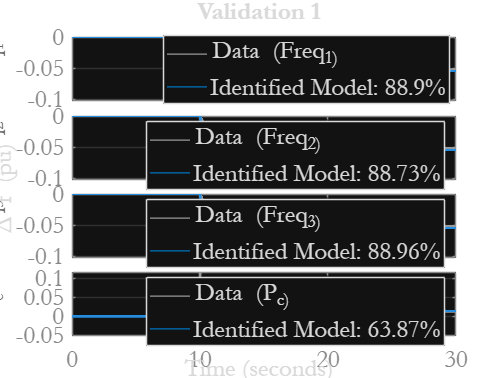

%Load validation data
%data_val1 = get_data("id_data\IBR="+inv+"_u=0.03.mat", inv);
%data_val1 = get_data("id_data\IBR="+inv+"_loc=16.mat", inv);
data_val1 = get_data("id_data\loc=5_d=0.4.mat", inv);


% Performance on validation data
f = figure;

compare(data_val1,power_sys);
xlabel('Time'),ylabel('\Delta f (pu)'),title('Validation 1')
legend({'Data','Identified Model'}, "Location","best")
grid on

fontsize(gcf, 25, "pixels")
fontname(gcf, "Garamond")
fig = gcf;
obj = findobj(fig,'Type','hggroup');
for idx = 1:numel(obj)
    for jdx = 1:numel(obj(idx).Children)
        obj(idx).Children(jdx).LineWidth = 2;
    end
end

% Identified physical values

params_id = getpar(power_sys, 'value');


id_M = params_id(1:3)

id_M =     0.6787
    1.8869
    0.0027


id_D = params_id(4:6)

id_D =     0.7000
    1.7076
    0.5270


id_R_sg = params_id(7)

id_R_sg = 1.4087

id_T_sg = params_id(8)

id_T_sg = 5.8925

id_R_c = params_id(9)

id_R_c = 3.7542

id_T_c = params_id(10)

id_T_c = 0.0087

id_T_mpc = params_id(11)

id_T_mpc = 0.6979

id_K_mpc = params_id(12)

id_K_mpc = 72.3393

id_K_dis = params_id(13:15)

id_K_dis =     0.3579
    0.3819
   32.3840


id_L = params_id(16:18)

id_L =   -14.6976
   -1.4161
   -4.8084


id_beta = params_id(19:21)

id_beta =     1.8908
    5.3171
   -0.8033



power_sys_ssm = idss(power_sys);
A_ssm = power_sys_ssm.A;
B_ssm = power_sys_ssm.B;
C_ssm = power_sys_ssm.C;
D_ssm = power_sys_ssm.D;

save("COI_models\DIS_model_inv="+inv+".mat",'A_ssm','B_ssm','C_ssm','D_ssm', 'id_M', 'id_D', 'id_R_sg', "id_R_c"	, "id_T_sg", "id_T_c", "id_T_mpc", 'id_K_mpc', "id_K_dis")
 

function [A,B,C,Dsys] = ssm(M, D, R_sg, T_sg, R_c, T_c, T_mpc, K_mpc, K_dis, L, beta, h)  
    A11 = zeros(3,3);
    A12 = eye(3);
    A13 = zeros(3,1);
    A14 = zeros(3,1);
    A15 = zeros(3,1);
 
    Lap = [-L(1)-L(2),L(1),L(2); L(1),-L(1)-L(3),L(3); L(2),L(3),-L(2)-L(3)];

    A21 = -diag(1./M) * Lap;
    A22 = diag([-D(1)/M(1), -D(2)/M(2), -D(3)/M(3)]);
    A23 = [beta(1)/M(1); beta(2)/M(2); beta(3)/M(3)];
    A24 = [1/M(1);0;0];
    A25 = zeros(3,1);

    A31 = zeros(1,3);
    A32 = -1/(T_sg*R_sg)*(1/sum(M))*M;
    A33 = -1/T_sg;
    A34 = 0;
    A35 = 0;
    
    A41 = zeros(1,3);
    A42 = [-1/(T_c*R_c),0,0];
    A43 = 0;
    A44 = -1/T_c;
    A45 = K_mpc;

    A51 = zeros(1,3);
    A52 = zeros(1,3);
    A53 = 0;
    A54 = 0;
    A55 = -1/T_mpc;
    
    A = [A11, A12, A13, A14, A15; A21, A22, A23, A24, A25; A31, A32, A33, A34, A35; A41, A42, A43, A44, A45; A51, A52, A53, A54, A55];

    Bd = [zeros(3,1); -K_dis(1); -K_dis(2);-K_dis(3); zeros(3,1)];
    Bu = [zeros(8,1); 1/T_mpc];
    B = [Bd, Bu];

    C = [zeros(3,3), eye(3), zeros(3,3); zeros(1,7), eye(1), zeros(1,1)];
    Dsys = zeros(4,2);
end


function [data_loaded] = get_data(name, inv)

    inverters = [43,44,52,53,54,55,56,57];
    f2s = [26,26,26,12,26,26,26,11];
    f3s = [21,21,21,23,21,2,2,26];
    
    dict_f2 = dictionary(inverters, f2s);
    dict_f3 = dictionary(inverters, f3s);
    

    S = load(name);
    h = S.h;
    t = S.t;
    d_1 = S.d_1 + S.d_2 + S.d_3 + S.d_4 + S.d_5 + S.d_6 + S.d_7 + S.d_8;
    
    u_field = ['Pmpc_' char(inv)];
    f1_field = ['f_' char(inv)];
    f2_field = ['f_bus_' num2str(dict_f2(inv))];
    f3_field = ['f_bus_' num2str(dict_f3(inv))];
    Pe_field = ['Pe_' char(inv)];

    u_1  = S.(u_field);
    y_1  = S.(f1_field);
    y_2  = S.(f2_field);
    y_3  = S.(f3_field);
    y_4  = S.(Pe_field);
    
    data_loaded = iddata([y_1, y_2, y_3, y_4], [d_1, u_1], h);
    data_loaded.OutputName = {'Freq_1', 'Freq_2', 'Freq_3',  'P_c'};
    data_loaded.InputName = {'P_dis', 'P_mpc'};
    data_loaded.Tstart = 0;
    data_loaded.TimeUnit = 's';
end
